clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = ".png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "./tex/images/";
% addpath("../CVX-arm64/");
% cvx_setup;
mkdir(SAVE_DIR);


k_1 = 7.29;
a_0_1 = 1;
T_1 = 0.38;
xi = 0;
k_2 = 9.46;
a_0_2 = 1;
T_2 = 1;
T = 0.25;
A_g = 7.68;
omega_g = 0.3;

## Task 1

TF_plant = tf([k_2], [T_2, a_0_2]) * tf([k_1], [T_1, a_0_1]);
ss_plant_continious = ss(TF_plant);
poles_ss_plant_continious = pole(ss_plant_continious);
ss_plant_discrete = c2d(ss_plant_continious, T)

ss_plant_discrete =
 
  A = 
            x1       x2
   x1   0.3581  -0.2104
   x2   0.3198   0.9387
 
  B = 
           u1
   x1   1.279
   x2  0.3728
 
  C = 
          x1     x2
   y1      0  11.34
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


eig(ss_plant_discrete.A)

ans =     0.5179
    0.7788


Gamma = [0 1; 0 0];
H = [1 1];
assert(rank(ctrb(ss_plant_discrete.A, ss_plant_discrete.B)) == 2);
assert(rank(obsv(Gamma, H)) == 2);
model_disc = c2d(ss(Gamma, [0; 0], H, 0), T);
eig(Gamma), eig(model_disc.A)

ans =      0
     0


ans =      1
     1


M = sylvester(ss_plant_discrete.A, -Gamma, ss_plant_discrete.B * H);
K = H * inv(M)

K =     0.6122    1.3780


ss_plant_discrete.A - ss_plant_discrete.B * K, eig(ss_plant_discrete.A - ss_plant_discrete.B * K)

ans =    -0.4250   -1.9729
    0.0915    0.4250


ans = 1.0e-08 *

   -0.5460
    0.5460


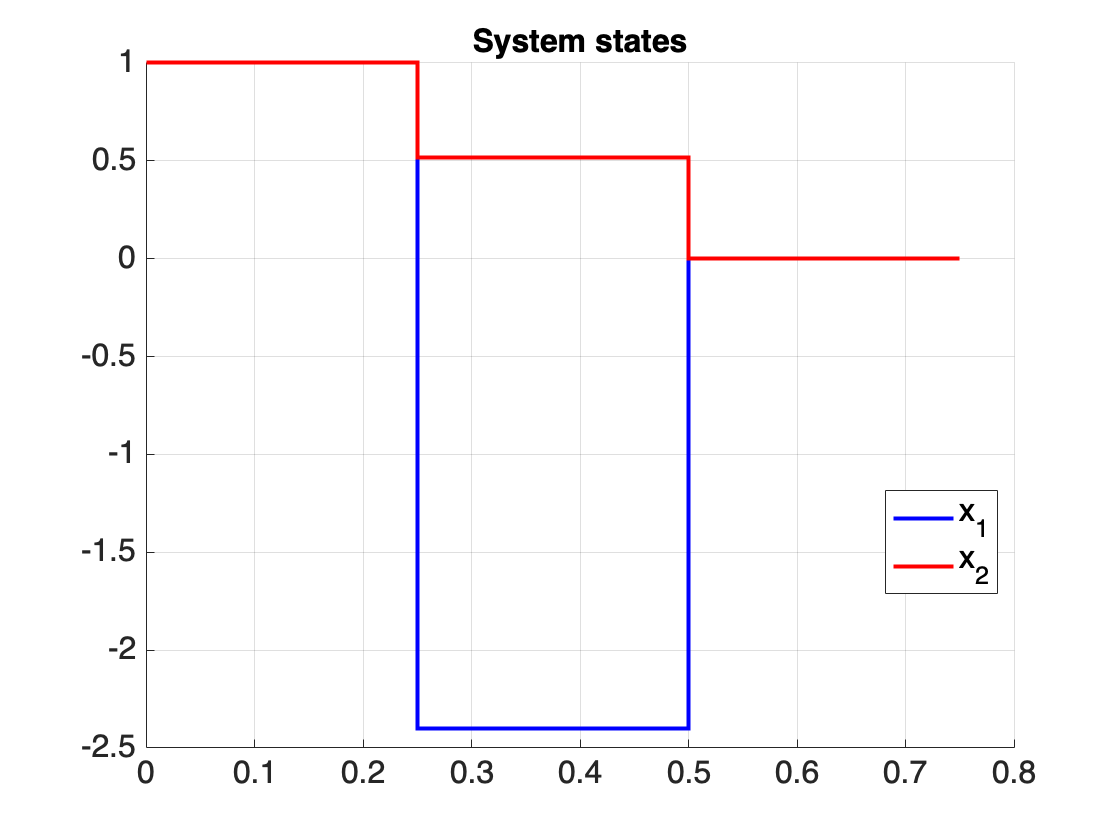


sim_res = sim("task1.slx", 0.75);
clf;
title("System states");
hold on;
stairs(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.x.time, sim_res.x.data(:,2), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
grid on;
legend({'x_1', 'x_2'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task1" + SAVE_EXT);

## Task 2

A_gen = [0 omega_g; -omega_g 0];
ss_gen = ss(A_gen, [0; 0], [A_g 0], 0);
ss_gen_disc = c2d(ss_gen, T);

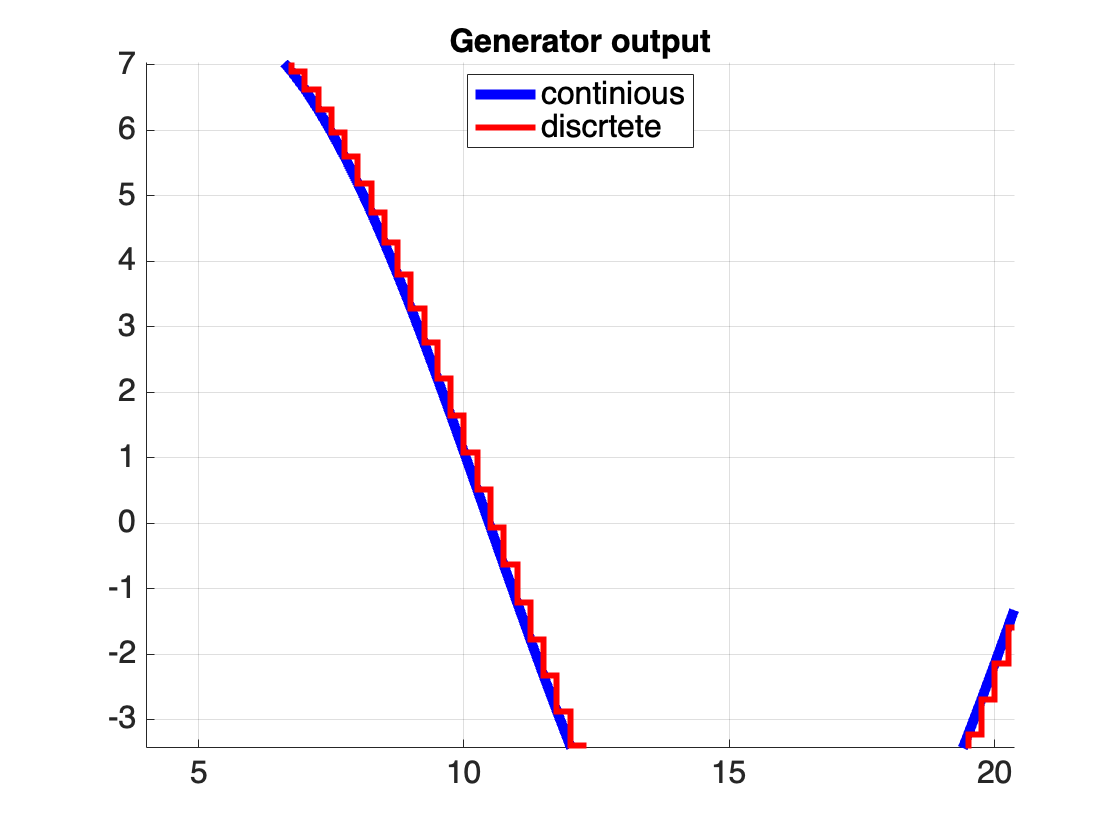

sim_res = sim("task2.slx", 25);
clf;
title("Generator output");
hold on;
plot(sim_res.gen_c.time, sim_res.gen_c.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.gen_d.time, sim_res.gen_d.data, 'LineWidth', 3, 'Color', 'red', 'LineStyle', '-');
grid on;
legend({'continious', 'discrtete'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_generator" + SAVE_EXT);

## Task 3

A_m = 9.8;
omega = 0.18;
sub_1_gen = [0 omega; -omega 0]

sub_1_gen =          0    0.1800
   -0.1800         0


sub_2_gen = [-5 6 0 0; -6 -5 0 0; 0 0 0 1; 0 0 0 0]

sub_2_gen =     -5     6     0     0
    -6    -5     0     0
     0     0     0     1
     0     0     0     0


### subtask 1

T_1 = 1;
discr_sys_1 = ss([0 1; -1 2*cos(T_1*omega)], [0; 0], [1, 0], 0, T_1);
init_1 = [0; A_m *sin(omega*T_1)];

### subtask 2

T_2 = 0.25;
discr_sys_2 = ss(sub_2_gen, [0; 0; 0; 0], [1 0 0.03 0], 0);
init_2 = [sin(2.5); cos(2.5); 0; 1]

init_2 =     0.5985
   -0.8011
         0
    1.0000


discr_sys_2 = c2d(discr_sys_2, T_2)

discr_sys_2 =
 
  A = 
            x1       x2       x3       x4
   x1  0.02027   0.2858        0        0
   x2  -0.2858  0.02027        0        0
   x3        0        0        1     0.25
   x4        0        0        0        1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     1     0  0.03     0
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


### Modeling

function task_3(exp_name)
    global SAVE_EXT;
    global SAVE_DIR;
    sim_res = sim("lab1/task3.slx", 20);
    h = figure();
    title("System state")
    hold on
    plot(sim_res.g_1_cont.time, sim_res.g_1_cont.data(:,1), 'LineWidth', 1, 'Color', 'blue', 'LineStyle', '-')
    plot(sim_res.g_1_discr.time, sim_res.g_1_discr.data(:,1), 'LineWidth', 1, 'Color', 'red', 'LineStyle', '--')
    legend(["$g(t)$", "$g(kT)$"],Interpreter="latex")
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state_1." + SAVE_EXT)

    h = figure();
    title("System state")
    hold on
    plot(sim_res.g_2_cont.time, sim_res.g_2_cont.data(:,1), 'LineWidth', 1, 'Color', 'blue', 'LineStyle', '-')
    plot(sim_res.g_2_discr.time, sim_res.g_2_discr.data(:,1), 'LineWidth', 1, 'Color', 'red', 'LineStyle', '--')
    legend(["$g(t)$", "$g(kT)$"],Interpreter="latex")
    grid on
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state_2." + SAVE_EXT)
end

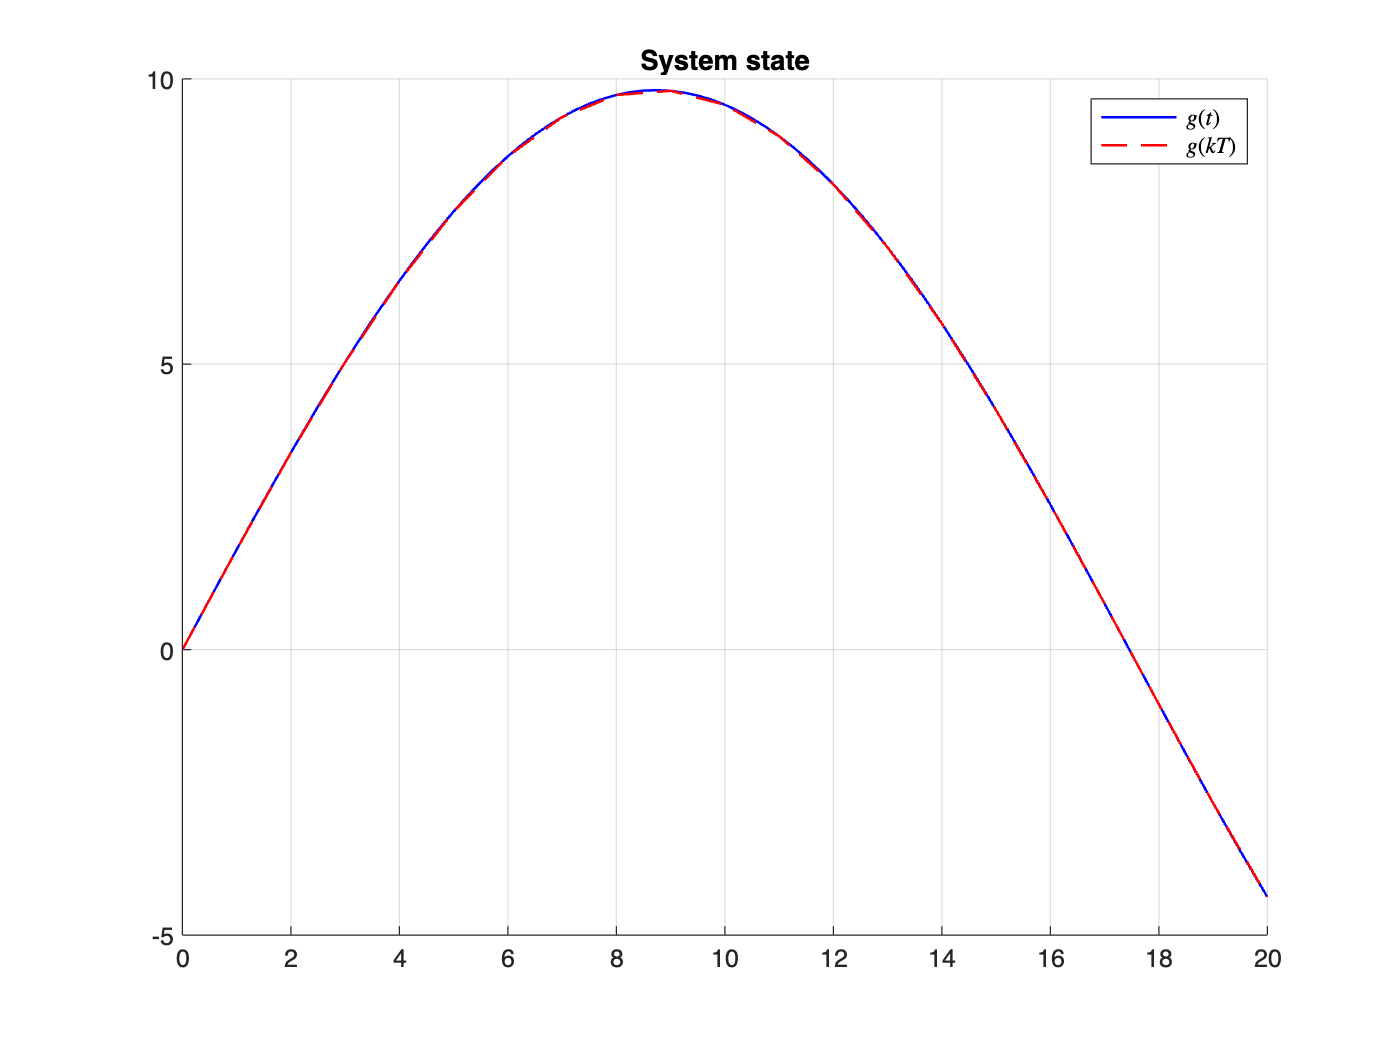

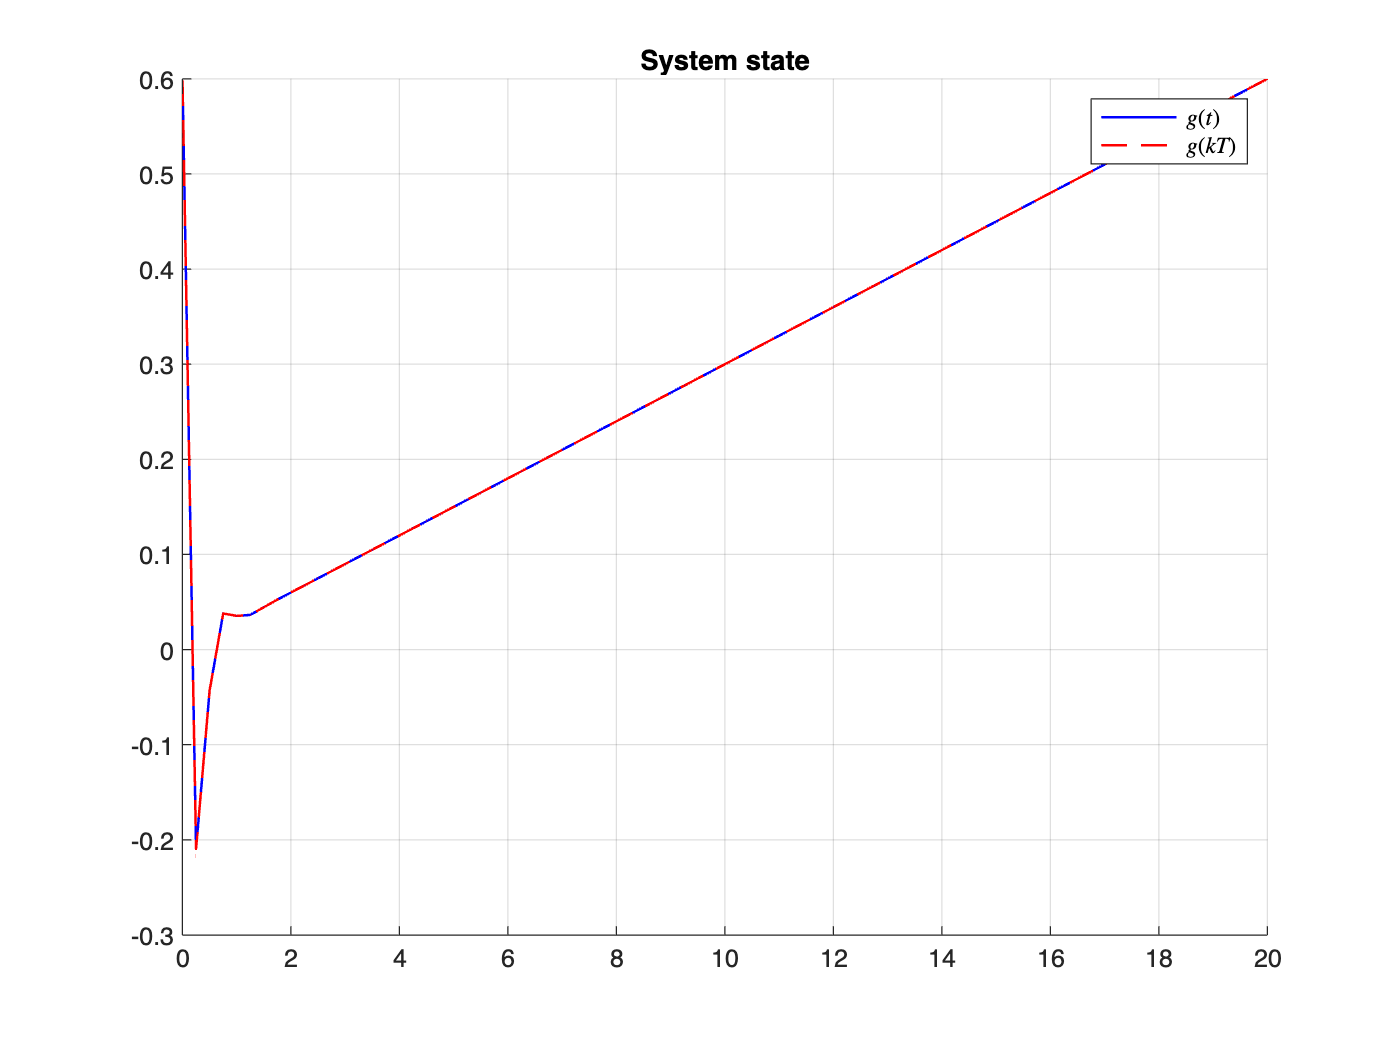

task_3("task3")